% load a file and process a bit, removing some bad samples at the 
% very beginning
load 'working.mat'
data = dataset - dataset(5,:);
pos_left = data(:, 2);
pos_right = data(:, 3);
pos_times = data(:, 1);

% distance between wheel constant
d = 0.254;

% calculate velocities (ang and lin)
vel_data = diff(data);
vel_left = vel_data(:, 2) ./ vel_data(:, 1);
vel_right = vel_data(:, 3) ./ vel_data(:, 1);
vel_times = vel_data(:, 1);
vel = (vel_left + vel_right) ./ 2;
w_exp = (vel_left - vel_right) ./ d;

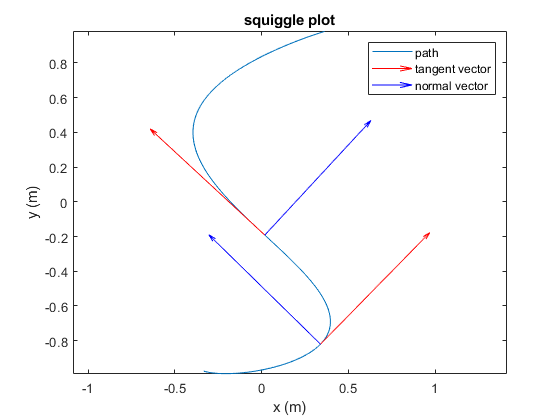

% plot theoretical path
t = 0:0.125:3.2/0.125; %205 steps
a = 0.125;

% the theoretical equations
r = [0.3960*cos(2.65*((a*t)+1.4));-0.99*sin((a*t) + 1.4);0*t];
v = abs(a).^(-2).*(a.^6.*(0.1E1.*cos(0.14E1+a.*t).^2+0.11236E1.*sin( ...
  0.371E1+0.265E1.*a.*t).^2).^(-6).*(0.2809E1.*cos(0.14E1+a.*t).^5.* ...
  cos(0.371E1+0.265E1.*a.*t)+0.106E1.*cos(0.14E1+a.*t).^4.*sin( ...
  0.14E1+a.*t).*sin(0.371E1+0.265E1.*a.*t)+0.631238E1.*cos(0.14E1+ ...
  a.*t).^3.*cos(0.371E1+0.265E1.*a.*t).*sin(0.371E1+0.265E1.*a.*t) ...
  .^2+0.238203E1.*cos(0.14E1+a.*t).^2.*sin(0.14E1+a.*t).*sin( ...
  0.371E1+0.265E1.*a.*t).^3+0.35463E1.*cos(0.14E1+a.*t).*cos( ...
  0.371E1+0.265E1.*a.*t).*sin(0.371E1+0.265E1.*a.*t).^4+0.133823E1.* ...
  sin(0.14E1+a.*t).*sin(0.371E1+0.265E1.*a.*t).^5).^2).^(1/2);
w = a.^3.*abs(a).^(-2).*(0.1E1.*cos(0.14E1+a.*t).^2+ ...
  0.11236E1.*sin(0.371E1+0.265E1.*a.*t).^2).^(-3).*((-0.2809E1).* ...
  cos(0.14E1+a.*t).^5.*cos(0.371E1+0.265E1.*a.*t)+(-0.106E1).*cos( ...
  0.14E1+a.*t).^4.*sin(0.14E1+a.*t).*sin(0.371E1+0.265E1.*a.*t)+( ...
  -0.631238E1).*cos(0.14E1+a.*t).^3.*cos(0.371E1+0.265E1.*a.*t).* ...
  sin(0.371E1+0.265E1.*a.*t).^2+(-0.238203E1).*cos(0.14E1+a.*t).^2.* ...
  sin(0.14E1+a.*t).*sin(0.371E1+0.265E1.*a.*t).^3+(-0.35463E1).*cos( ...
  0.14E1+a.*t).*cos(0.371E1+0.265E1.*a.*t).*sin(0.371E1+0.265E1.*a.* ...
  t).^4+(-0.133823E1).*sin(0.14E1+a.*t).*sin(0.371E1+0.265E1.*a.*t) ...
  .^5);
That = [(-0.10494E1).*a.*abs(a).^(-1).*sin(0.371E1+0.265E1.*a.*t).*( ...
  0.9801E0.*cos(0.14E1+a.*t).^2+0.110124E1.*sin(0.371E1+0.265E1.*a.* ...
  t).^2).^(-1/2);(-0.99E0).*a.*abs(a).^(-1).*cos(0.14E1+a.*t).*( ...
  0.9801E0.*cos(0.14E1+a.*t).^2+0.110124E1.*sin(0.371E1+0.265E1.*a.* ...
  t).^2).^(-1/2);0*t];
Nhat = [cos(0.14E1+a.*t).*((-0.278091E1).*cos(0.14E1+a.*t).*cos(0.371E1+ ...
  0.265E1.*a.*t)+(-0.10494E1).*sin(0.14E1+a.*t).*sin(0.371E1+ ...
  0.265E1.*a.*t)).*(cos(0.14E1+a.*t).^4.*(0.773346E1.*cos(0.371E1+ ...
  0.265E1.*a.*t).^2+(-0.217626E-15).*sin(0.14E1+a.*t).^2)+ ...
  0.868932E1.*cos(0.14E1+a.*t).^2.*cos(0.371E1+0.265E1.*a.*t).^2.* ...
  sin(0.371E1+0.265E1.*a.*t).^2+0.27531E0.*sin(0.28E1+2.*a.*t).^2.* ...
  sin(0.371E1+0.265E1.*a.*t).^2+(0.174101E-14.*cos(0.371E1+0.265E1.* ...
  a.*t).^2+0.123735E1.*sin(0.14E1+a.*t).^2).*sin(0.371E1+0.265E1.* ...
  a.*t).^4+0.364786E0.*csc(0.14E1+a.*t).^2.*sin(0.28E1+2.*a.*t).^3.* ...
  sin(0.742E1+0.53E1.*a.*t)+0.163949E1.*sin(0.28E1+2.*a.*t).*sin( ...
  0.371E1+0.265E1.*a.*t).^2.*sin(0.742E1+0.53E1.*a.*t)).^(-1/2);sin( ...
  0.371E1+0.265E1.*a.*t).*(0.294776E1.*cos(0.14E1+a.*t).*cos( ...
  0.371E1+0.265E1.*a.*t)+0.111236E1.*sin(0.14E1+a.*t).*sin(0.371E1+ ...
  0.265E1.*a.*t)).*(cos(0.14E1+a.*t).^4.*(0.773346E1.*cos(0.371E1+ ...
  0.265E1.*a.*t).^2+(-0.217626E-15).*sin(0.14E1+a.*t).^2)+ ...
  0.868932E1.*cos(0.14E1+a.*t).^2.*cos(0.371E1+0.265E1.*a.*t).^2.* ...
  sin(0.371E1+0.265E1.*a.*t).^2+0.27531E0.*sin(0.28E1+2.*a.*t).^2.* ...
  sin(0.371E1+0.265E1.*a.*t).^2+(0.174101E-14.*cos(0.371E1+0.265E1.* ...
  a.*t).^2+0.123735E1.*sin(0.14E1+a.*t).^2).*sin(0.371E1+0.265E1.* ...
  a.*t).^4+0.364786E0.*csc(0.14E1+a.*t).^2.*sin(0.28E1+2.*a.*t).^3.* ...
  sin(0.742E1+0.53E1.*a.*t)+0.163949E1.*sin(0.28E1+2.*a.*t).*sin( ...
  0.371E1+0.265E1.*a.*t).^2.*sin(0.742E1+0.53E1.*a.*t)).^(-1/2);0*t]; ...
vl = (a.^2.*(0.9801E0.*cos(0.14E1+a.*t).^2+0.110124E1.*sin(0.371E1+ ...
  0.265E1.*a.*t).^2)).^(1/2)+(-1/2).*a.^3.*d.*abs(a).^(-2).*(0.1E1.* ...
  cos(0.14E1+a.*t).^2+0.11236E1.*sin(0.371E1+0.265E1.*a.*t).^2).^( ...
  -3).*((-0.2809E1).*cos(0.14E1+a.*t).^5.*cos(0.371E1+0.265E1.*a.*t) ...
  +(-0.106E1).*cos(0.14E1+a.*t).^4.*sin(0.14E1+a.*t).*sin(0.371E1+ ...
  0.265E1.*a.*t)+(-0.631238E1).*cos(0.14E1+a.*t).^3.*cos(0.371E1+ ...
  0.265E1.*a.*t).*sin(0.371E1+0.265E1.*a.*t).^2+(-0.238203E1).*cos( ...
  0.14E1+a.*t).^2.*sin(0.14E1+a.*t).*sin(0.371E1+0.265E1.*a.*t).^3+( ...
  -0.35463E1).*cos(0.14E1+a.*t).*cos(0.371E1+0.265E1.*a.*t).*sin( ...
  0.371E1+0.265E1.*a.*t).^4+(-0.133823E1).*sin(0.14E1+a.*t).*sin( ...
  0.371E1+0.265E1.*a.*t).^5);
vr = (a.^2.*(0.9801E0.*cos(0.14E1+a.*t).^2+0.110124E1.*sin(0.371E1+ ...
  0.265E1.*a.*t).^2)).^(1/2)+(1/2).*a.^3.*d.*abs(a).^(-2).*(0.1E1.* ...
  cos(0.14E1+a.*t).^2+0.11236E1.*sin(0.371E1+0.265E1.*a.*t).^2).^( ...
  -3).*((-0.2809E1).*cos(0.14E1+a.*t).^5.*cos(0.371E1+0.265E1.*a.*t) ...
  +(-0.106E1).*cos(0.14E1+a.*t).^4.*sin(0.14E1+a.*t).*sin(0.371E1+ ...
  0.265E1.*a.*t)+(-0.631238E1).*cos(0.14E1+a.*t).^3.*cos(0.371E1+ ...
  0.265E1.*a.*t).*sin(0.371E1+0.265E1.*a.*t).^2+(-0.238203E1).*cos( ...
  0.14E1+a.*t).^2.*sin(0.14E1+a.*t).*sin(0.371E1+0.265E1.*a.*t).^3+( ...
  -0.35463E1).*cos(0.14E1+a.*t).*cos(0.371E1+0.265E1.*a.*t).*sin( ...
  0.371E1+0.265E1.*a.*t).^4+(-0.133823E1).*sin(0.14E1+a.*t).*sin( ...
  0.371E1+0.265E1.*a.*t).^5);

% plot the squiggle 
figure()
plot(r(1,:),r(2,:)),hold on
quiver(r(1,100),r(2,100),That(1,100),That(2,100),'r')
quiver(r(1,100),r(2,100),Nhat(1,100),Nhat(2,100),'b')
quiver(r(1,50),r(2,50),That(1,50),That(2,50),'r')
quiver(r(1,50),r(2,50),Nhat(1,50),Nhat(2,50),'b')
quiver(r(1,50),r(2,50),That(1,50),That(2,50),'r')
quiver(r(1,50),r(2,50),Nhat(1,50),Nhat(2,50),'b')
axis equal
title('squiggle plot');
legend('path', 'tangent vector', 'normal vector');
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
print('plots/TheoPath', '-dpng', '-r300');

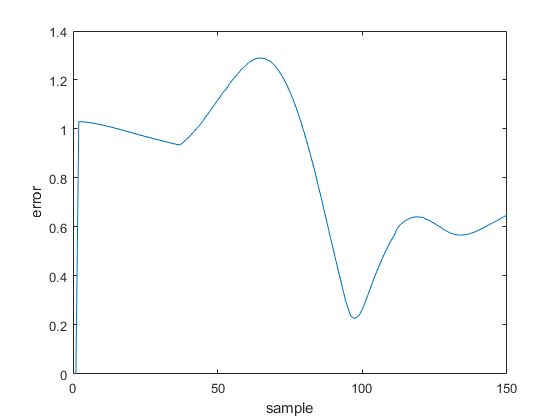

% compile data for experimental position data
pos_exp = zeros(size(pos_left,1), 3);
that_exp = zeros(size(pos_left,1), 2);
for i = 2:1:size(pos_times, 1) - 2 
    that_exp(i, 1) = cos(pos_exp(i - 1, 3));
    that_exp(i, 2) = sin(pos_exp(i - 1, 3));
    pos_exp(i, :) = [(vel(i) * vel_times(i) * that_exp(i, 1)) + pos_exp(i - 1, 1) (vel(i) * vel_times(i) * that_exp(i, 2)) + pos_exp(i - 1, 2)...
                     (w_exp(i) * vel_times(i)) + pos_exp(i - 1, 3)];
    err(i,:) = sqrt((pos_exp(i, 1)-r(1,i))^2+(pos_exp(i,1)-r(2,i))^2);
end
% the last couple data points seem to frequently get messed up
figure()
pos_exp = pos_exp(1:end-2, :);
plot(1:1:size(pos_times, 1) - 2,err(:,1));
ylabel('error')
xlabel('sample')
print('plots/error', '-dpng', '-r300');

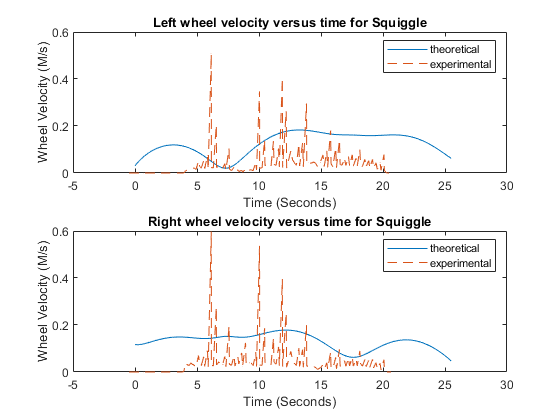

% Plot wheel velocities
figure()

subplot(2,1,1);
plot(t, vl), hold on
plot(pos_times(1:end-1), vel_left / 6, '--')
title('Left wheel velocity versus time for Squiggle');
legend('theoretical','experimental')
xlabel('Time (Seconds)');
ylabel('Wheel Velocity (M/s)');

subplot(2,1,2);
plot(t, vr), hold on
plot(pos_times(1:end-1), vel_right / 6, '--')
title('Right wheel velocity versus time for Squiggle');
legend('theoretical','experimental')
xlabel('Time (Seconds)');
ylabel('Wheel Velocity (M/s)');

print('plots/WheelVelocities', '-dpng', '-r300');

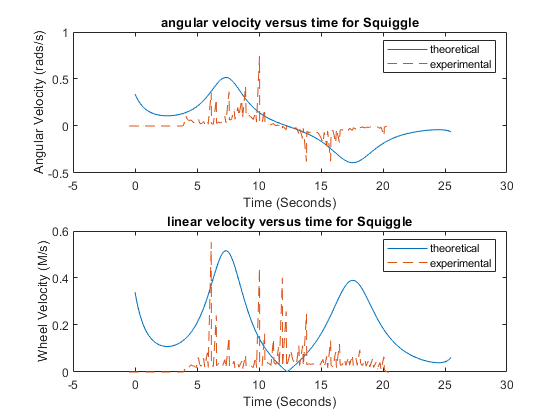

% Plot linear and angular speed versus time
figure()
subplot(2,1,1);
plot(t, w), hold on
plot(pos_times(1:end-1), -w_exp / 6, '--')
title('angular velocity versus time for Squiggle');
legend('theoretical','experimental')
xlabel('Time (Seconds)');
ylabel('Angular Velocity (rads/s)');

subplot(2,1,2);
plot(t, v), hold on
plot(pos_times(1:end-1), vel / 6, '--')
title('linear velocity versus time for Squiggle');
legend('theoretical','experimental')
xlabel('Time (Seconds)');
ylabel('Wheel Velocity (M/s)');
print('plots/VAndWVsTime', '-dpng', '-r300');

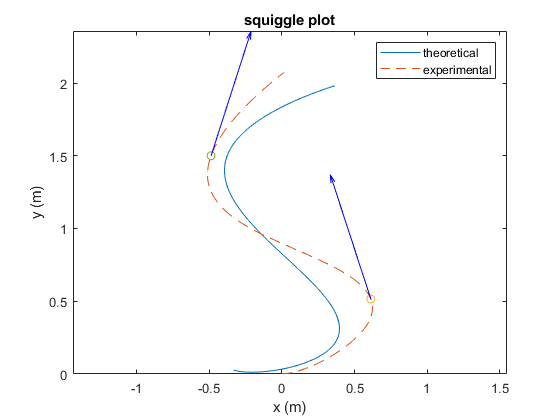

% plot paths
figure()
plot(r(1,:),r(2,:) + 1),hold on
plot(pos_exp(:, 1), -pos_exp(:, 2), '--')    
plot(pos_exp(72, 1), -pos_exp(72, 2), 'o')
quiver(pos_exp(72,1),-pos_exp(72,2),that_exp(72,1),-that_exp(72,2),'b')
plot(pos_exp(120, 1), -pos_exp(120, 2), 'o')
quiver(pos_exp(120,1),-pos_exp(120,2),that_exp(120,1),-that_exp(120,2),'b')
axis equal 
title('squiggle plot');
legend('theoretical', 'experimental');
xlabel('x (m)');
ylabel('y (m)');
print('plots/Paths', '-dpng', '-r300');